%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 151433*0.946

W = 1.4326e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1561; %ft^2
AR = 8.75

AR = 8.7500

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 116.8707

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;
K = 1/(e*pi*AR)

K = 0.0404


%Fuselage Parameters
Df = 15.17; %ft
LNose = 13.33; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 1.5 %ft

DBase = 1.5000

ABase = pi*DBase^2/4

ABase = 1.7671

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8290

Sexp = 1.3143e+03

Re = 7.5922e+07

SweepMaxT = -0.9821

FF = 1.7037

Swet = 2.7009e+03

CDo = 0.0065


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0021


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0015


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.2628

CDoFuse = 0.0057


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0062


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0036


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 1.1502e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag

CDoTotal = 0.0220


%Induced Drag Factor
% [TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
% AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
% V=V*1.688
% M = V/SpeedSound
% 
% Ne = 0; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)


CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
   CD2(x) = CDoTotal2 + K2*CL(x)^2
   
   if CL(x)/CD2(x)>LDMax
       
       LDMax2 = CL(x)/CD2(x)
       
   end
   
end

CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237    0.0236    0.0234    0.0233    0.0231    0.0230    0.0229    0.0227    0.0226    0.0225    0.0224    0.0224    0.0223    0.0222    0.0222    0.0221    0.0221    0.0220    0.0220    0.0220    0.0220


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 0.4554

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 0.4640

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 0.9104

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 0.9271

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 1.3643

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 1.3885

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 1.8167

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 1.8473

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 2.2672

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 2.3026

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 2.7151

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 2.7537

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 3.1601

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 3.1997

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 3.6017

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 3.6400

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 4.0394

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 4.0737

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 4.4728

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 4.5001

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 4.9015

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 4.9187

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 5.3251

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 5.3288

CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 5.7431

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 6.1552

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 6.5610

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 6.9602

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 7.3526

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 7.7378

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 8.1155

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 8.4855

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 8.8475

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 9.2014

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 9.5471

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 9.8842

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 10.2127

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 10.5326

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 10.8436

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 11.1457

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 11.4388

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 11.7230

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 11.9981

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 12.2643

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 12.5215

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 12.7697

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 13.0090

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 13.2395

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 13.4612

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 13.6742

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 13.8786

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 14.0745

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 14.2621

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 14.4414

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 14.6126

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 14.7759

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 14.9313

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.0791

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.2193

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.3523

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.4780

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.5967

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.7086

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.8138

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 15.9126

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.0050

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.0912

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.1715

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.2460

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.3149

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.3783

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.4364

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.4895

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.5375

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.5808

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.6195

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.6536

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.6835

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7092

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7309

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7488

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7629

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7734

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7805

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7843

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


LDMax = 16.7850

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0321    0.0317    0.0313    0.0309    0.0305    0.0301    0.0298    0.0294    0.0291    0.0287    0.0284    0.0281    0.0278    0.0275    0.0272    0.0269    0.0266    0.0264    0.0261    0.0258    0.0256    0.0254    0.0251    0.0249    0.0247    0.0245    0.0243    0.0241    0.0239    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


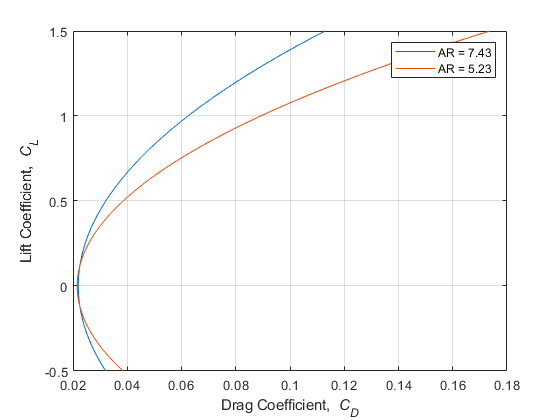


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
hold on
plot (CD2,CL)
hold off
legend('AR = 7.43','AR = 5.23')


LDMax

LDMax = 16.7850

LDMax2

LDMax2 = 5.3288